clc; clear;

stik = 40;     % Antal stikprøver
tests = 100;     % Antal terningekast / udtagelser af stikprøven
test_range = [30, 35];
step = 0.25;

ms = zeros(1, stik);
Y = zeros(stik, tests);

for i = 1:stik
    for j = 1:tests
        Y(i,j) = randi(test_range, 1);
    end
    ms(i) = mean(Y(i,:));
end


histogram(ms, min(test_range):step:max(test_range), "Normalization","pdf")
hold on

% Den gennemsnitlige afvigelse
mean_gns = mean(ms)

mean_gns = 32.5060

stdafv = std(ms, 1)

stdafv = 0.2069

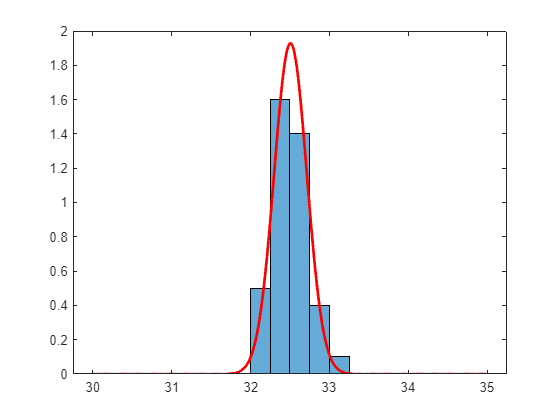


% PLotte fordelingen oveni
dist = makedist("Normal","mu",mean_gns,"sigma",stdafv);
x = linspace(min(test_range), max(test_range), 1000);

df = pdf(dist, x);

plot(x, df, Color="red", LineStyle="-", LineWidth=2)
hold off





dist2 = makedist("Normal", "mu",mean_gns,"sigma",stdafv)

dist2 =   NormalDistribution

  Normal distribution
       mu =   32.506
    sigma = 0.206891



df2 = random(dist2, stik*tests, 1);


[h,p,stats] = chi2gof(df2,'Alpha', 0.05)

h = 0

p = 0.7585

stats = struct with fields:
    chi2stat: 4.1825
          df: 7
       edges: [31.8014 31.9395 32.0777 32.2159 32.3541 32.4923 32.6304 32.7686 32.9068 33.0450 33.1831]
           O: [10 61 262 590 952 1015 675 320 98 17]
           E: [12.3329 63.9625 242.1252 597.5108 961.8423 1.0103e+03 692.5094 309.6629 90.2845 19.4500]
